clear all
clc

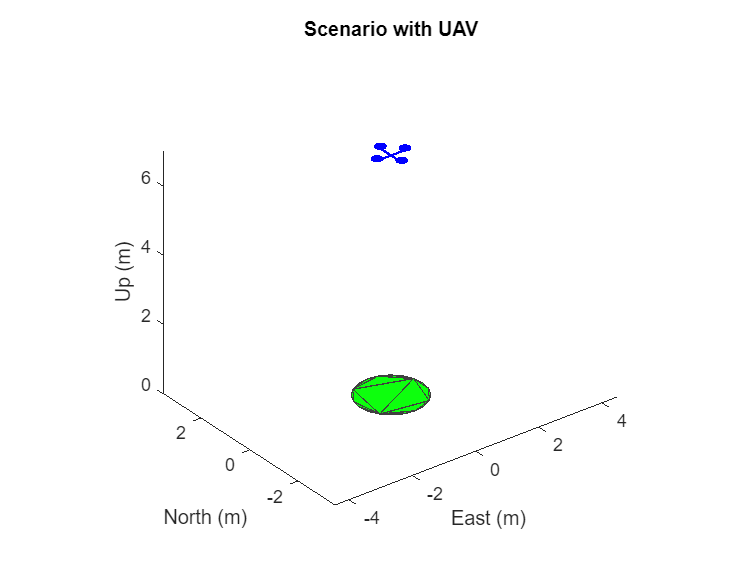

% Control Parameters
Px = 3; Py = 3; Pz = 4;
Vx = 0.5; Vy = 0.5; Vz = 1;

Px_RRT = 5; Py_RRT = 5; Pz_RRT = 6;

UAVSampleTime = 0.001;
Gravity = 9.81;
DroneMass = 0.1;
InitialPosition = [0 0 -7];  
InitialOrientation = [0 0 0];
InitialVelocity = [0 0 0];
InitialAcceleration = [0 0 0];


% Scenario
Scenario = uavScenario("UpdateRate",100,"ReferenceLocation",[0 0 0]);
addMesh(Scenario,"cylinder",{[0 0 1] [0 .01]},[0 1 0]);

platUAV = uavPlatform("UAV",Scenario, ...
                      "ReferenceFrame","NED", ...
                      "InitialPosition",InitialPosition, ...
                      "InitialOrientation",eul2quat(InitialOrientation));

updateMesh(platUAV,"quadrotor",{1.2},[0 0 1],eul2tform([0 0 pi]));

AzimuthResolution = 0.5;      
ElevationResolution = 2;
MaxRange = 30;
AzimuthLimits = [-179 179];
ElevationLimits = [-25 25];

LidarModel = uavLidarPointCloudGenerator("UpdateRate",10, ...
                                         "MaxRange",MaxRange, ...
                                         "RangeAccuracy",3, ...
                                         "AzimuthResolution",AzimuthResolution, ...
                                         "ElevationResolution",ElevationResolution, ...
                                         "AzimuthLimits",AzimuthLimits, ...
                                         "ElevationLimits",ElevationLimits, ...                                       
                                         "HasOrganizedOutput",true);
myLidarSensor = uavSensor("Lidar",platUAV,LidarModel, ...
          "MountingLocation",[0 0 -0.4], ...
          "MountingAngles",[0 0 180]);
show3D(Scenario);
title("Scenario with UAV");
exportgraphics(gcf, 'UAVscenario.pdf', 'ContentType', 'vector');

% Obstacles
Buildings = [
    10  0   15  4 3   0.8 0.6 0.6;  
    20 10   15  3 5   0.6 0.8 0.6;  
    10 20   12  3 3   0.6 0.6 0.9;  
    -5   5  10  2 3   0.7 0.7 0.9;  
     3  -4  9  3 2   0.6 0.8 0.9;  
    -4   8  8  3 4   0.8 0.7 0.9;
    5  15   10  3 2   0.9 0.7 0.8; 
];

for i = 1:size(Buildings,1)
    x = Buildings(i,1);
    y = Buildings(i,2);
    h = Buildings(i,3);
    wx = Buildings(i,4);
    wy = Buildings(i,5);
    color = Buildings(i,6:8);
    basePolygon = [
        x - wx/2, y - wy/2;
        x + wx/2, y - wy/2;
        x + wx/2, y + wy/2;
        x - wx/2, y + wy/2
    ];
    addMesh(Scenario,"polygon",{basePolygon,[0 h]}, color);
end

Trees = [
    8  5  3 0.4  0.4 0.7 0.4;
    16 12 4 0.5  0.3 0.6 0.3;
    12 22 3 0.4  0.5 0.8 0.5;
    22 18 5 0.6  0.3 0.7 0.3;
    7  17 4 0.5  0.4 0.6 0.4;
    -5 0 4 0.4  0.4 0.7 0.4;  
    0  -6 3 0.5  0.3 0.6 0.3;   
    -8   4 5 0.6  0.5 0.8 0.5;
    3 -2 3 0.4  0.3 0.7 0.3;
];

for i = 1:size(Trees,1)
    x = Trees(i,1);
    y = Trees(i,2);
    h = Trees(i,3);
    r = Trees(i,4);
    color = Trees(i,5:7);

    theta = linspace(0,2*pi,20)';
    circle = [r*cos(theta)+x, r*sin(theta)+y];

    addMesh(Scenario,"polygon",{circle,[0 h]}, color);
end

Points = [
    0, 0, 7, 0.5, 0.4, 0.7, 0.4;       
    10, 24, 14, 0.5, 0.4, 0.7, 0.4;   
    20, 0, 12, 0.5, 0.4, 0.7, 0.4;
];

for i = 1:size(Points,1)
    x = Points(i,1);
    y = Points(i,2);
    h = Points(i,3);
    r = Points(i,4);
    color = Points(i,5:7);

    numPoints = 30;
    radius = 0.8;
    theta = linspace(0, 2*pi, numPoints);
    circle = [x + radius*cos(theta)', y + radius*sin(theta)'];
    addMesh(Scenario,"polygon",{circle, [0 0.01]}, [1 0 0]);
end

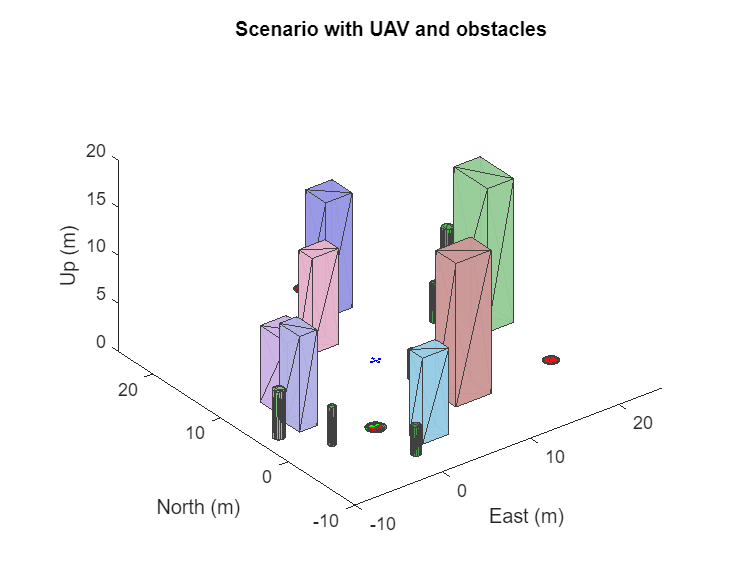

figure;
show3D(Scenario);
xlim([-10 25])
ylim([-10 25])
zlim([0 20])

title("Scenario with UAV and obstacles");
exportgraphics(gcf, 'obstacles_scenario.pdf', 'ContentType', 'vector');

**Occupancy Map**

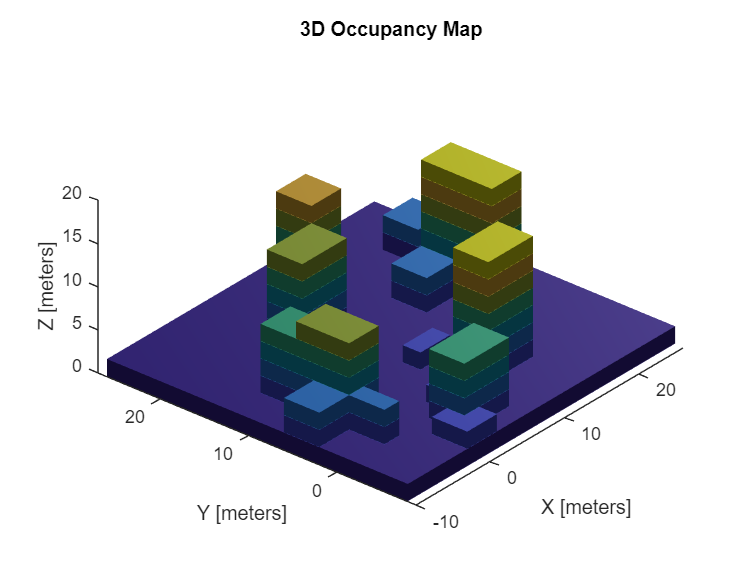

voxelSize = 0.5;  
map3D = occupancyMap3D(voxelSize);
allPoints = [];

for i = 1:size(Buildings,1)
    x = Buildings(i,1);
    y = Buildings(i,2);
    h = Buildings(i,3);
    wx = Buildings(i,4);
    wy = Buildings(i,5);

    [xGrid,yGrid,zGrid] = meshgrid( ...
        x - wx/2 : voxelSize : x + wx/2, ...
        y - wy/2 : voxelSize : y + wy/2, ...
        0 : voxelSize : h);

    points = [xGrid(:), yGrid(:), zGrid(:)];
    allPoints = [allPoints; points];
end

for i = 1:size(Trees,1)
    x = Trees(i,1);
    y = Trees(i,2);
    h = Trees(i,3);
    r = Trees(i,4);

    theta = linspace(0, 2*pi, 20);
    for z = 0:voxelSize:h
        xx = r*cos(theta)' + x;
        yy = r*sin(theta)' + y;
        zz = z*ones(length(theta),1);
        points = [xx, yy, zz];
        allPoints = [allPoints; points];
    end
end

minX = floor(min(allPoints(:,1))) - 1;
maxX = ceil(max(allPoints(:,1))) + 1;
minY = floor(min(allPoints(:,2))) - 1;
maxY = ceil(max(allPoints(:,2))) + 1;

[xGround,yGround] = meshgrid(minX:voxelSize:maxX, minY:voxelSize:maxY);
zGround = zeros(size(xGround));
groundPoints = [xGround(:), yGround(:), zGround(:)];
allPoints = [allPoints; groundPoints];

setOccupancy(map3D, allPoints, 1);

figure;
show(map3D);
title('3D Occupancy Map');
zlim([0 20])
exportgraphics(gcf, 'occupancy.pdf', 'ContentType', 'vector');

**RRT with  3-D Dubins motion primitives**

map3D.FreeThreshold = map3D.OccupiedThreshold;

waypoints_occ = [
    0, 0, 7, pi/2;
    10, 24, 14, pi/4;
    20, 0, 12, 0
];

fullPathStates = [];

ss = ExampleHelperUAVStateSpace("MaxRollAngle",pi/4,...
                                "AirSpeed",5,...
                                "FlightPathAngleLimit",[-0.2 0.2],...
                                "Bounds",[-5 100; -5 100; 0 20; -pi pi]);

sv = validatorOccupancyMap3D(ss,"Map",map3D);
sv.ValidationDistance = 0.5;

planner = plannerRRT(ss,sv);
planner.MaxConnectionDistance = 50;
planner.GoalBias = 0.10;
planner.MaxIterations = 1000;
planner.GoalReachedFcn = @(~,x,y)(norm(x(1:3)-y(1:3)) < 3);

figure("Name","Path with Waypoints");
hMap = show(map3D);
hold on
scatter3(hMap, waypoints_occ(:,1), waypoints_occ(:,2), waypoints_occ(:,3), 50, "filled",'MarkerFaceColor', 'r', "DisplayName", "Waypoints");
text(waypoints_occ(1,1)+1,waypoints_occ(1,2)+1,waypoints_occ(1,3)+1, 'Start', 'Color', 'red', 'FontSize', 10);
text(waypoints_occ(end,1)+1,waypoints_occ(end,2)+1,waypoints_occ(end,3)+1, 'Goal', 'Color', 'green', 'FontSize', 10);
exportgraphics(gcf, 'occupancy_waypoints.pdf', 'ContentType', 'vector');


for i = 1:size(waypoints_occ, 1) - 1
    currentStartPose = waypoints_occ(i,:);
    currentGoalPose = waypoints_occ(i+1,:);
    threshold = [(currentGoalPose(1:3)-5)' (currentGoalPose(1:3)+5)'; -pi pi];
    setWorkspaceGoalRegion(ss,currentGoalPose,threshold);

    fprintf('Planning segment from [%.1f %.1f %.1f] to [%.1f %.1f %.1f]\n', ...
            currentStartPose(1), currentStartPose(2), currentStartPose(3), ...
            currentGoalPose(1), currentGoalPose(2), currentGoalPose(3));

    [pthObjSegment, solnInfoSegment] = plan(planner, currentStartPose, currentGoalPose);

    if (solnInfoSegment.IsPathFound)
        fprintf('Path found for segment %d.\n', i);

        if isempty(fullPathStates)
            fullPathStates = pthObjSegment.States;
        else
            fullPathStates = [fullPathStates; pthObjSegment.States(2:end,:)];
        end

        plot3(pthObjSegment.States(:,1), pthObjSegment.States(:,2), pthObjSegment.States(:,3), 'b-', 'LineWidth', 1.5, 'DisplayName', sprintf('Segment %d Path', i));

    else
        fprintf('Path NOT found for segment %d. Stopping.\n', i);
        fullPathStates = []; 
        break; 
    end
end

Planning segment from [0.0 0.0 7.0] to [10.0 24.0 14.0]


Path found for segment 1.


Planning segment from [10.0 24.0 14.0] to [20.0 0.0 12.0]


Path found for segment 2.


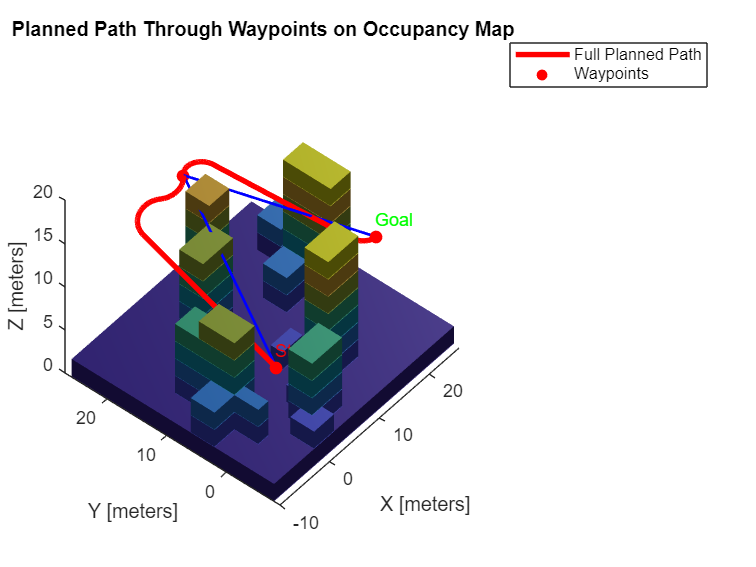

if ~isempty(fullPathStates)
    interpolatedPathObj = navPath(ss, fullPathStates); 
    interpolate(interpolatedPathObj, 1000);
    SavedPath = interpolatedPathObj.States;
    save('PlannedPathData.mat','SavedPath');

    hReference = plot3(interpolatedPathObj.States(:,1), ...
        interpolatedPathObj.States(:,2), ...
        interpolatedPathObj.States(:,3), ...
        "LineWidth",3,"Color","r","DisplayName","Full Planned Path");

    legend([hReference, findobj(hMap,'Type','scatter')]);
else
    disp('No complete path found through all waypoints.');
end

hold off
title("Planned Path Through Waypoints on Occupancy Map");
zlim([0 20]);
exportgraphics(gcf, 'RTTpath.pdf', 'ContentType', 'vector');

n = size(interpolatedPathObj.States, 1);
pathStates = interpolatedPathObj.States;
step = 3;
RRTwaypoints_ENU = pathStates(1:step:end, 1:3);
RRTwaypoints = [RRTwaypoints_ENU(:,2), RRTwaypoints_ENU(:,1), -RRTwaypoints_ENU(:,3)];

out = sim('RRTpath.slx');

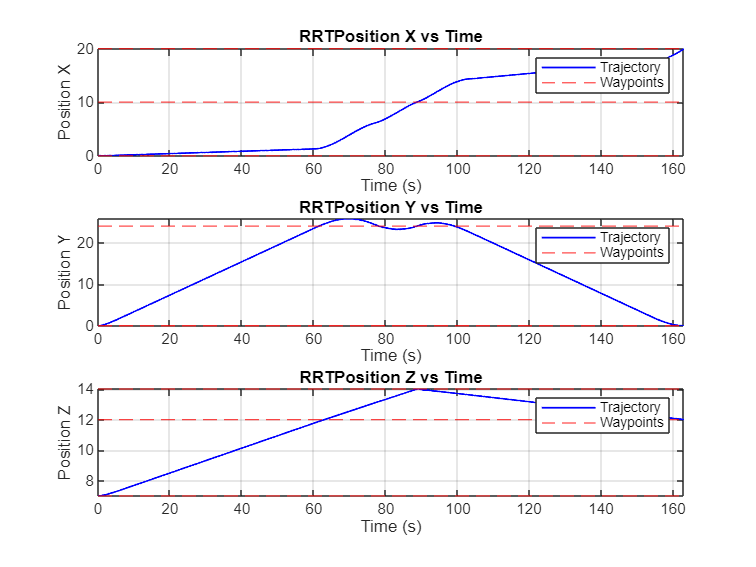

RRTPosition = out.RRTPosition;
RTTtime = RRTPosition.Time;
RRTpos = RRTPosition.Data;
RRTx = squeeze(RRTpos(2, 1, :)); 
RRTy = squeeze(RRTpos(1, 1, :)); 
RRTz = -squeeze(RRTpos(3, 1, :)); 
RRTPositionError = out.RRTPositionError;
RRTposerr = RRTPositionError.Data;
RRTxerr = squeeze(RRTposerr(2, 1, :)); 
RRTyerr = squeeze(RRTposerr(1, 1, :)); 
RRTzerr = -squeeze(RRTposerr(3, 1, :)); 
RRTYawError = out.RRTYawError;
RRTyawerr = RRTYawError.Data;
RRTyawerr = squeeze(RRTyawerr(1, 1, :)); 
RRTControlSignal = out.RRTControlSignal;
RRTcontrol_roll = RRTControlSignal.Roll;
RRTcontrol_pitch = RRTControlSignal.Pitch;
RRTcontrol_yawrate = RRTControlSignal.YawRate;
RRTcontrol_thrust = RRTControlSignal.Thrust;
RRTcontrol_time = RRTcontrol_thrust.Time;
RRTcontrol_roll = squeeze(RRTcontrol_roll.Data); 
RRTcontrol_pitch = squeeze(RRTcontrol_pitch.Data); 
RRTcontrol_yawrate = squeeze(RRTcontrol_yawrate.Data); 
RRTcontrol_thrust = squeeze(RRTcontrol_thrust.Data); 

figure

subplot(3,1,1)
plot(RTTtime, RRTx, 'b', 'LineWidth', 1); hold on;
h1 = yline(waypoints_occ(:,1), 'r--', 'LineWidth', 0.7);
xlabel('Time (s)');
ylabel('Position X');
title('RRTPosition X vs Time');
grid on;
xlim([0 RTTtime(end)]);
legend('Trajectory', 'Waypoints');

subplot(3,1,2)
plot(RTTtime, RRTy, 'b', 'LineWidth', 1); hold on;
h2 = yline(waypoints_occ(:,2), 'r--', 'LineWidth', 0.7);
xlabel('Time (s)');
ylabel('Position Y');
title('RRTPosition Y vs Time');
grid on;
xlim([0 RTTtime(end)]);
legend('Trajectory', 'Waypoints');

subplot(3,1,3)
plot(RTTtime, RRTz, 'b', 'LineWidth', 1); hold on;
h3 = yline(waypoints_occ(:,3), 'r--', 'LineWidth', 0.7);
xlabel('Time (s)');
ylabel('Position Z');
title('RRTPosition Z vs Time');
grid on;
xlim([0 RTTtime(end)]);
legend('Trajectory', 'Waypoints');
exportgraphics(gcf, 'RTTtraj.pdf', 'ContentType', 'vector');

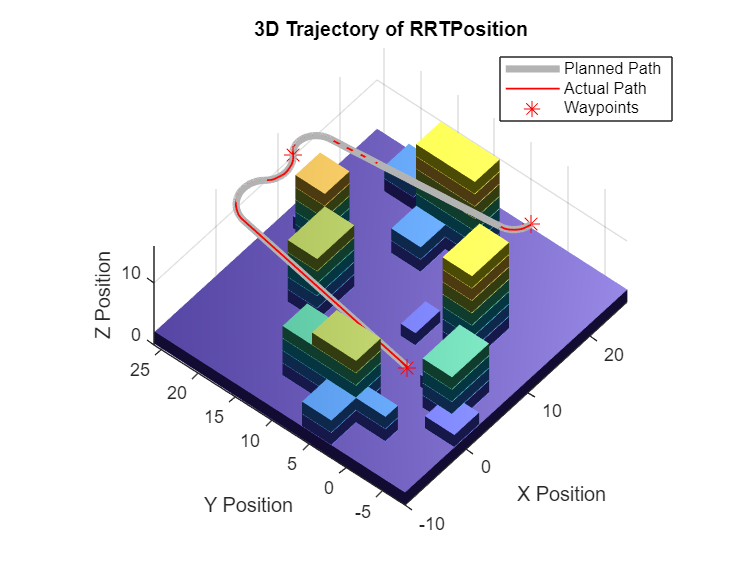

figure
hMap = show(map3D);
hold on;

hPlanned = plot3(interpolatedPathObj.States(:,1), ...
                 interpolatedPathObj.States(:,2), ...
                 interpolatedPathObj.States(:,3), ...
                 'LineWidth', 4, ...
                 'Color', [0.7 0.7 0.7 0.3], ...   
                 'DisplayName', 'Planned Path');

hActual = plot3(RRTx, RRTy, RRTz, ...
                'LineWidth', 1, ...
                'Color', 'r', ...
                'DisplayName', 'Actual Path');

hWaypoints = plot3(waypoints_occ(:,1), waypoints_occ(:,2), waypoints_occ(:,3), ...
                   'r*', ...
                   'MarkerSize', 10, ...
                   'MarkerFaceColor', 'r', ...
                   'DisplayName', 'Waypoints');

grid on;
xlabel('X Position');
ylabel('Y Position');
zlabel('Z Position');
title('3D Trajectory of RRTPosition');
axis equal;
legend([hPlanned, hActual, hWaypoints], 'Location', 'best');
exportgraphics(gcf, 'RTTpath_actual_planned.pdf', 'ContentType', 'vector');

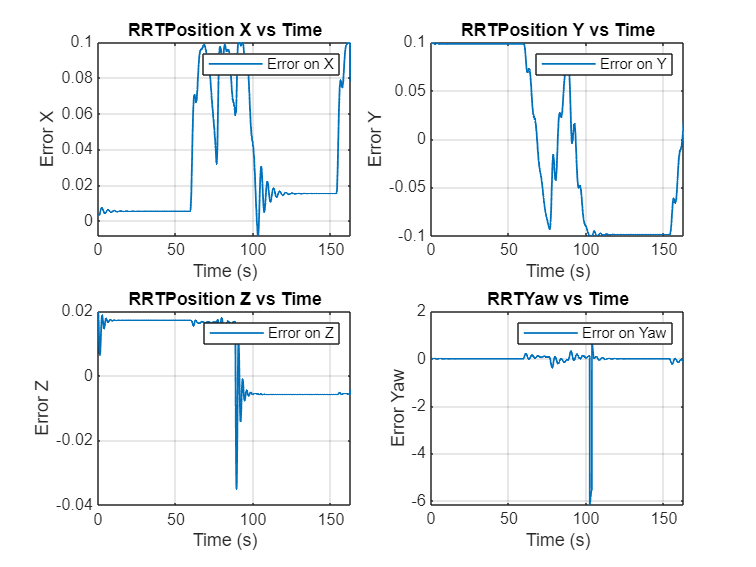

figure

subplot(2,2,1)
plot(RTTtime, RRTxerr,'LineWidth', 1); hold on;
xlabel('Time (s)');
ylabel('Error X');
title('RRTPosition X vs Time');
grid on;
xlim([0 RTTtime(end)]);
legend('Error on X');

subplot(2,2,2)
plot(RTTtime, RRTyerr , 'LineWidth', 1); hold on;
xlabel('Time (s)');
ylabel('Error Y');
title('RRTPosition Y vs Time');
grid on;
xlim([0 RTTtime(end)]);
legend('Error on Y');

subplot(2,2,3)
plot(RTTtime, RRTzerr, 'LineWidth', 1); hold on;
xlabel('Time (s)');
ylabel('Error Z');
title('RRTPosition Z vs Time');
grid on;
xlim([0 RTTtime(end)]);
legend('Error on Z');

subplot(2,2,4)
plot(RTTtime, RRTyawerr, 'LineWidth', 1); hold on;
xlabel('Time (s)');
ylabel('Error Yaw');
title('RRTYaw vs Time');
grid on;
xlim([0 RTTtime(end)]);
legend('Error on Yaw');
exportgraphics(gcf, 'RTTerror.pdf', 'ContentType', 'vector');

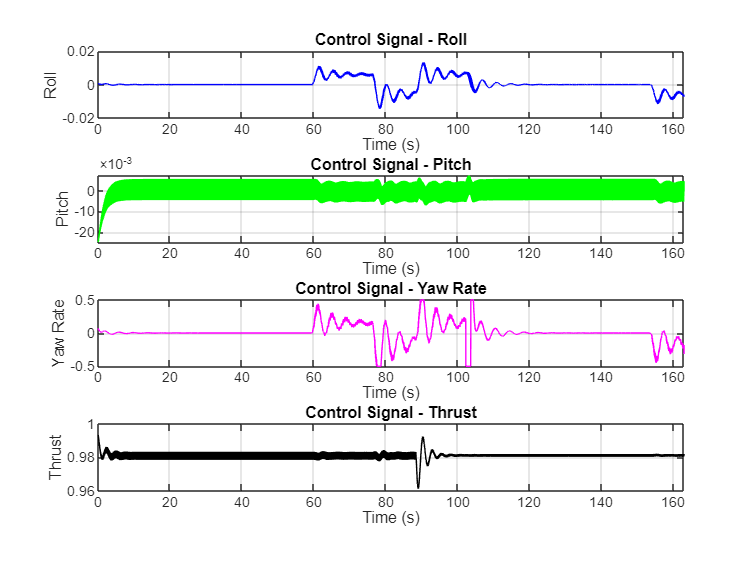

figure 

subplot(4,1,1)
plot(RRTcontrol_time, RRTcontrol_roll, 'b');
xlabel('Time (s)');
ylabel('Roll');
title('Control Signal - Roll');
grid on;
xlim([RRTcontrol_time(1), RRTcontrol_time(end)]);

subplot(4,1,2)
plot(RRTcontrol_time, RRTcontrol_pitch, 'g');
xlabel('Time (s)');
ylabel('Pitch');
title('Control Signal - Pitch');
grid on;
xlim([RRTcontrol_time(1), RRTcontrol_time(end)]);

subplot(4,1,3)
plot(RRTcontrol_time, RRTcontrol_yawrate, 'm');
xlabel('Time (s)');
ylabel('Yaw Rate');
title('Control Signal - Yaw Rate');
grid on;
xlim([RRTcontrol_time(1), RRTcontrol_time(end)]);

subplot(4,1,4)
plot(RRTcontrol_time, RRTcontrol_thrust, 'k');
xlabel('Time (s)');
ylabel('Thrust');
title('Control Signal - Thrust');
grid on;
xlim([RRTcontrol_time(1), RRTcontrol_time(end)]);
exportgraphics(gcf, 'RTTcntrl_inp.pdf', 'ContentType', 'vector');

**Obstacle Avoidance with UAV Toolbox**

Waypoints = [
    0, 0, -7;     
    24, 10, -14;    
    0, 20, -12;     
];
LookAheadOA = 0.4;

out = sim('ObstacleAvoidance.slx');

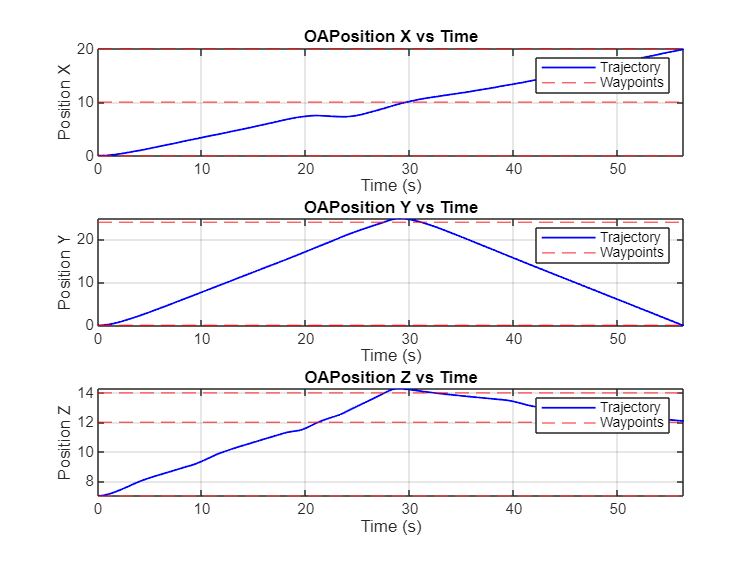

OAPosition = out.OAPosition;
OAtime = OAPosition.Time;
OApos = OAPosition.Data;
OAx = squeeze(OApos(2, 1, :)); 
OAy = squeeze(OApos(1, 1, :)); 
OAz = -squeeze(OApos(3, 1, :)); 
OAPositionError = out.OAPositionError;
OAposerr = OAPositionError.Data;
OAxerr = squeeze(OAposerr(2, 1, :)); 
OAyerr = squeeze(OAposerr(1, 1, :)); 
OAzerr = -squeeze(OAposerr(3, 1, :)); 
OAYawError = out.OAYawError;
OAyawerr = OAYawError.Data;
OAyawerr = squeeze(OAyawerr(1, 1, :)); 
OAControlSignal = out.OAControlSignal;
OAcontrol_roll = OAControlSignal.Roll;
OAcontrol_pitch = OAControlSignal.Pitch;
OAcontrol_yawrate = OAControlSignal.YawRate;
OAcontrol_thrust = OAControlSignal.Thrust;
OAcontrol_time = OAcontrol_thrust.Time;
OAcontrol_roll = squeeze(OAcontrol_roll.Data); 
OAcontrol_pitch = squeeze(OAcontrol_pitch.Data); 
OAcontrol_yawrate = squeeze(OAcontrol_yawrate.Data); 
OAcontrol_thrust = squeeze(OAcontrol_thrust.Data); 

figure

subplot(3,1,1)
plot(OAtime, OAx, 'b', 'LineWidth', 1); hold on;
h1 = yline(Waypoints(:,2), 'r--', 'LineWidth', 0.7);
xlabel('Time (s)');
ylabel('Position X');
title('OAPosition X vs Time');
grid on;
xlim([0 OAtime(end)]);
legend('Trajectory', 'Waypoints');

subplot(3,1,2)
plot(OAtime, OAy, 'b', 'LineWidth', 1); hold on;
h2 = yline(Waypoints(:,1), 'r--', 'LineWidth', 0.7);
xlabel('Time (s)');
ylabel('Position Y');
title('OAPosition Y vs Time');
grid on;
xlim([0 OAtime(end)]);
legend('Trajectory', 'Waypoints');

subplot(3,1,3)
plot(OAtime, OAz, 'b', 'LineWidth', 1); hold on;
h3 = yline(-Waypoints(:,3), 'r--', 'LineWidth', 0.7);
xlabel('Time (s)');
ylabel('Position Z');
title('OAPosition Z vs Time');
grid on;
xlim([0 OAtime(end)]);
legend('Trajectory', 'Waypoints');
exportgraphics(gcf, 'OA_traj.pdf', 'ContentType', 'vector');

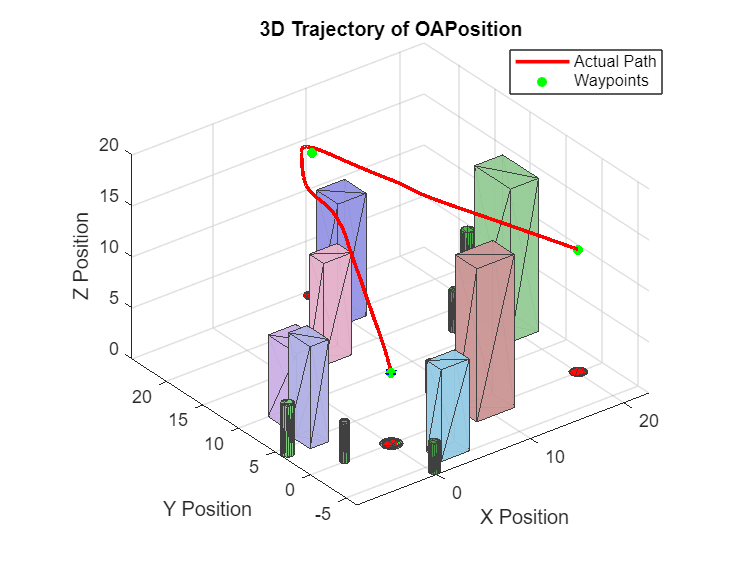

figure
hMap = show3D(Scenario);
hold on;
hActual = plot3(OAx, OAy, OAz, ...
                'LineWidth', 2, ...
                'Color', 'r', ...
                'DisplayName', 'Actual Path');

hWaypoints = plot3(Waypoints(:,2), Waypoints(:,1), -Waypoints(:,3), ...
                   'go', ...
                   'MarkerSize', 5, ...
                   'MarkerFaceColor', 'g', ...
                   'DisplayName', 'Waypoints');

grid on;
xlabel('X Position');
ylabel('Y Position');
zlabel('Z Position');
title('3D Trajectory of OAPosition');
axis equal;
legend([hActual, hWaypoints], 'Location', 'best');
zlim([0 20]);
exportgraphics(gcf, 'OA_path.pdf', 'ContentType', 'vector');

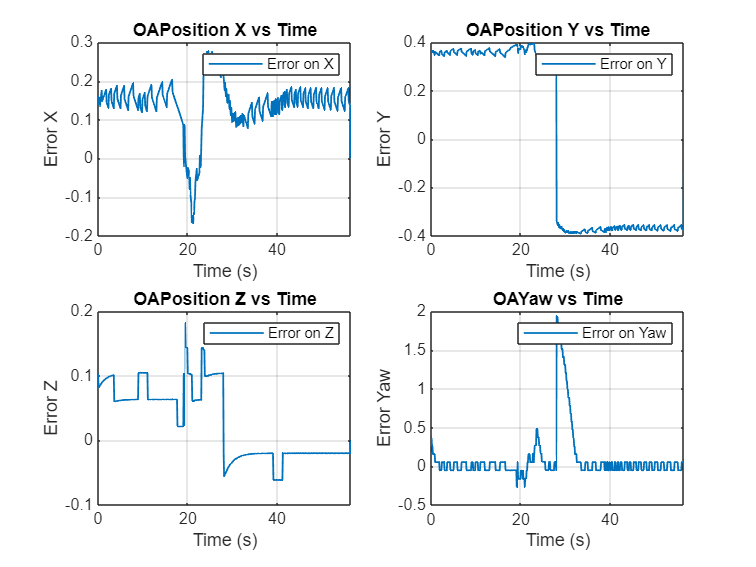

figure

subplot(2,2,1)
plot(OAtime, OAxerr,'LineWidth', 1); hold on;
xlabel('Time (s)');
ylabel('Error X');
title('OAPosition X vs Time');
grid on;
xlim([0 OAtime(end)]);
legend('Error on X');

subplot(2,2,2)
plot(OAtime, OAyerr , 'LineWidth', 1); hold on;
xlabel('Time (s)');
ylabel('Error Y');
title('OAPosition Y vs Time');
grid on;
xlim([0 OAtime(end)]);
legend('Error on Y');

subplot(2,2,3)
plot(OAtime, OAzerr, 'LineWidth', 1); hold on;
xlabel('Time (s)');
ylabel('Error Z');
title('OAPosition Z vs Time');
grid on;
xlim([0 OAtime(end)]);
legend('Error on Z');

subplot(2,2,4)
plot(OAtime, OAyawerr, 'LineWidth', 1); hold on;
xlabel('Time (s)');
ylabel('Error Yaw');
title('OAYaw vs Time');
grid on;
xlim([0 OAtime(end)]);
legend('Error on Yaw');
exportgraphics(gcf, 'OA_error.pdf', 'ContentType', 'vector');

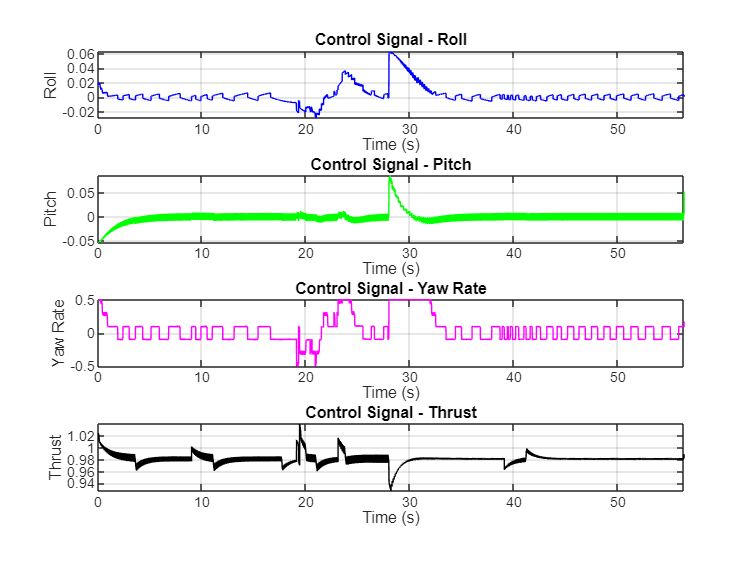


figure 

subplot(4,1,1)
plot(OAcontrol_time, OAcontrol_roll, 'b');
xlabel('Time (s)');
ylabel('Roll');
title('Control Signal - Roll');
grid on;
xlim([OAcontrol_time(1), OAcontrol_time(end)]);

subplot(4,1,2)
plot(OAcontrol_time, OAcontrol_pitch, 'g');
xlabel('Time (s)');
ylabel('Pitch');
title('Control Signal - Pitch');
grid on;
xlim([OAcontrol_time(1), OAcontrol_time(end)]);

subplot(4,1,3)
plot(OAcontrol_time, OAcontrol_yawrate, 'm');
xlabel('Time (s)');
ylabel('Yaw Rate');
title('Control Signal - Yaw Rate');
grid on;
xlim([OAcontrol_time(1), OAcontrol_time(end)]);

subplot(4,1,4)
plot(OAcontrol_time, OAcontrol_thrust, 'k');
xlabel('Time (s)');
ylabel('Thrust');
title('Control Signal - Thrust');
grid on;
xlim([OAcontrol_time(1), OAcontrol_time(end)]);
exportgraphics(gcf, 'OA_cntrinp.pdf', 'ContentType', 'vector');

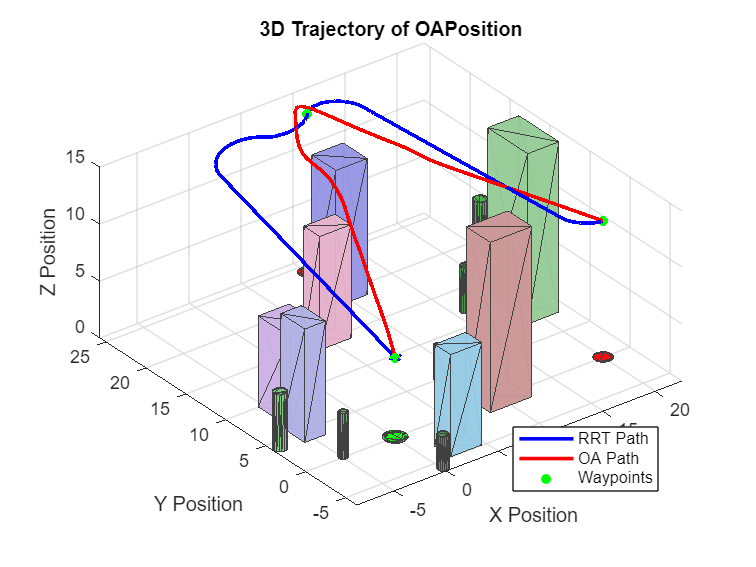

% Confronto

figure
hMap = show3D(Scenario);
hold on;

RRTActual = plot3(RRTx, RRTy, RRTz, ...
                'LineWidth', 2, ...
                'Color', 'b', ...
                'DisplayName', 'RRT Path');

OAActual = plot3(OAx, OAy, OAz, ...
                'LineWidth', 2, ...
                'Color', 'r', ...
                'DisplayName', 'OA Path');

hWaypoints = plot3(Waypoints(:,2), Waypoints(:,1), -Waypoints(:,3), ...
                   'go', ...
                   'MarkerSize', 5, ...
                   'MarkerFaceColor', 'g', ...
                   'DisplayName', 'Waypoints');

grid on;
xlabel('X Position');
ylabel('Y Position');
zlabel('Z Position');
title('3D Trajectory of OAPosition');
axis equal;
legend([RRTActual, OAActual, hWaypoints], 'Location', 'best');
exportgraphics(gcf, 'comparison.pdf', 'ContentType', 'vector');

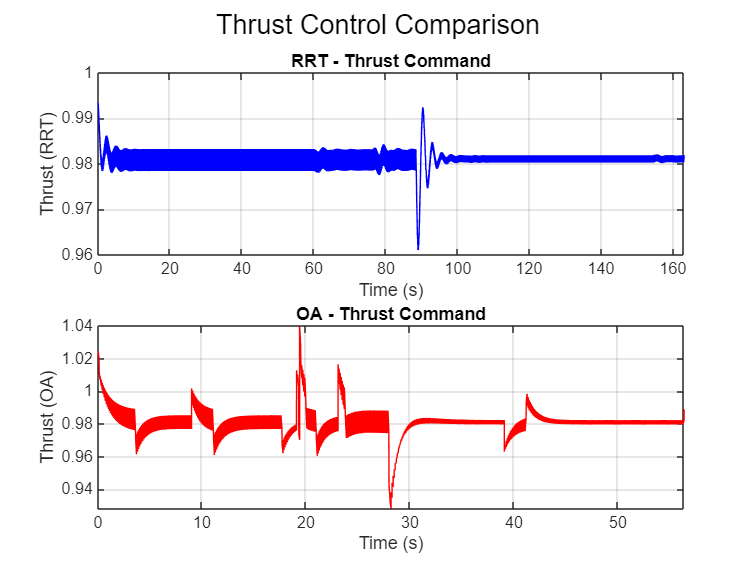

figure;

subplot(2,1,1);
plot(RRTcontrol_time, RRTcontrol_thrust, 'b');
xlabel('Time (s)');
ylabel('Thrust (RRT)');
title('RRT - Thrust Command');
grid on;
xlim([RRTcontrol_time(1), RRTcontrol_time(end)]);

subplot(2,1,2);
plot(OAcontrol_time, OAcontrol_thrust, 'r');
xlabel('Time (s)');
ylabel('Thrust (OA)');
title('OA - Thrust Command');
grid on;
xlim([OAcontrol_time(1), OAcontrol_time(end)]);

sgtitle('Thrust Control Comparison');
exportgraphics(gcf, 'thrust_control_comparison_subplot.pdf', 'ContentType', 'vector');

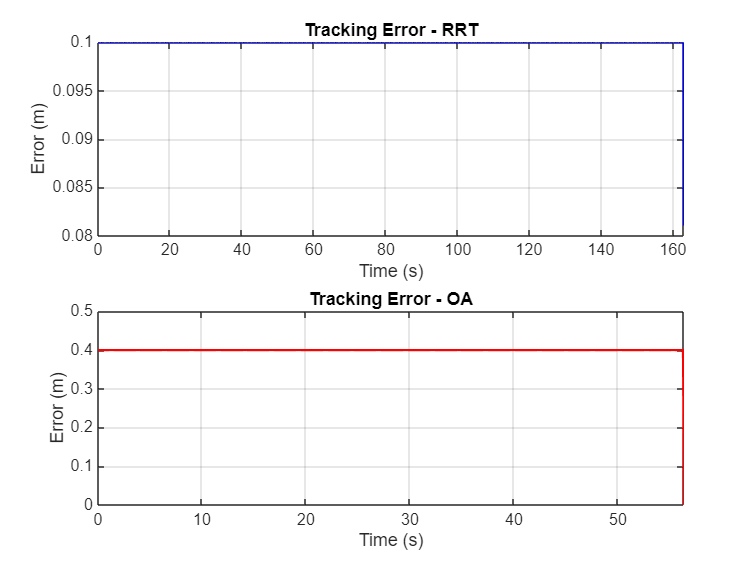

% RRT
max_thrust_RRT = max(RRTcontrol_thrust);
min_thrust_RRT = min(RRTcontrol_thrust);
mean_thrust_RRT = mean(RRTcontrol_thrust);

% OA
max_thrust_OA = max(OAcontrol_thrust);
min_thrust_OA = min(OAcontrol_thrust);
mean_thrust_OA = mean(OAcontrol_thrust);

%% TRACKING ERROR TOTALE (norma L2 punto a punto)
RRT_total_error = vecnorm([RRTxerr, RRTyerr, RRTzerr], 2, 2);
OA_total_error  = vecnorm([OAxerr, OAyerr, OAzerr], 2, 2);

figure;
subplot(2,1,1)
plot(RTTtime, RRT_total_error, 'b', 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Error (m)');
title('Tracking Error - RRT');
xlim([0 RTTtime(end)]);
grid on;

subplot(2,1,2)
plot(OAtime, OA_total_error, 'r', 'LineWidth', 1.2);
xlabel('Time (s)');
ylabel('Error (m)');
title('Tracking Error - OA');
xlim([0 OAtime(end)]);
grid on;

exportgraphics(gcf, '1_tracking_error_total.pdf', 'ContentType', 'vector');

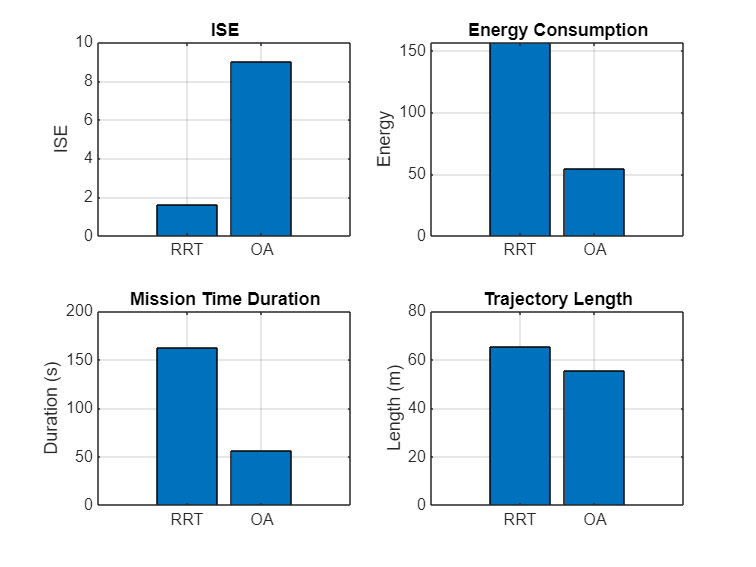

%% ERRORE INTEGRATO (ISE)
ISE_RRT = trapz(RTTtime, RRT_total_error.^2);
ISE_OA  = trapz(OAtime, OA_total_error.^2);

figure;
subplot(2,2,1);
bar([ISE_RRT, ISE_OA]);
set(gca, 'xticklabel', {'RRT', 'OA'});
ylabel('ISE');
title('ISE');
grid on;
%% CONSUMO ENERGETICO STIMATO (Thrust^2)
Energy_RRT = trapz(RRTcontrol_time, RRTcontrol_thrust.^2);
Energy_OA  = trapz(OAcontrol_time, OAcontrol_thrust.^2);

subplot(2,2,2);
bar([Energy_RRT, Energy_OA]);
set(gca, 'xticklabel', {'RRT', 'OA'});
ylabel('Energy');
title('Energy Consumption');
grid on;
%% TEMPO DI COMPLETAMENTO
duration_RRT = RTTtime(end);
duration_OA  = OAcontrol_time(end); 

subplot(2,2,3);
bar([duration_RRT, duration_OA]);
set(gca, 'xticklabel', {'RRT', 'OA'});
ylabel('Duration (s)');
title('Mission Time Duration');
grid on;

%% LUNGHEZZA TRAIETTORIA
subplot(2,2,4);
RRT_traj = [RRTx, RRTy, RRTz];
OA_traj  = [OAx, OAy, OAz];

traj_length_RRT = sum(vecnorm(diff(RRT_traj), 2, 2));
traj_length_OA  = sum(vecnorm(diff(OA_traj), 2, 2));

bar([traj_length_RRT, traj_length_OA]);
set(gca, 'xticklabel', {'RRT', 'OA'});
ylabel('Length (m)');
title('Trajectory Length');
grid on;
exportgraphics(gcf, 'confronti_vari.pdf', 'ContentType', 'vector');